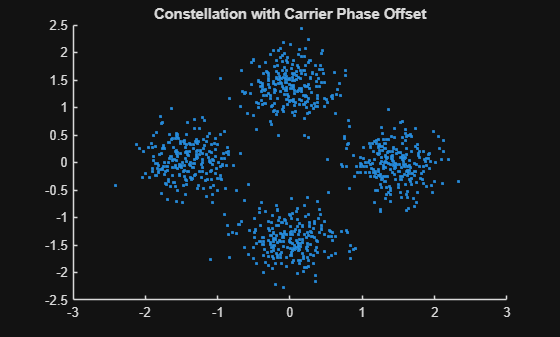

clc;
clear;
close all;

%% ----------------------------------
% PARAMETERS
%% ----------------------------------
N = 1000;
SNR_dB = 10;
phi = pi/4;     % Carrier phase offset (unknown)
Fs = 100;
Tb = 1;
t = 0:1/Fs:Tb-1/Fs;

%% ----------------------------------
% 1. QPSK TRANSMISSION
%% ----------------------------------
bits = randi([0 1], 1, 2*N);

b1 = bits(1:2:end);
b2 = bits(2:2:end);

s = (2*b1-1) + 1j*(2*b2-1); % QPSK symbols

%% ----------------------------------
% 2. Carrier Phase Uncertainty
%% ----------------------------------
% Apply unknown phase rotation
r = s .* exp(1j*phi);

% Add AWGN
r = awgn(r, SNR_dB, 'measured');

%% ----------------------------------
% Constellation with Phase Error
%% ----------------------------------
figure;
scatter(real(r), imag(r), '.');
title('Constellation with Carrier Phase Offset');

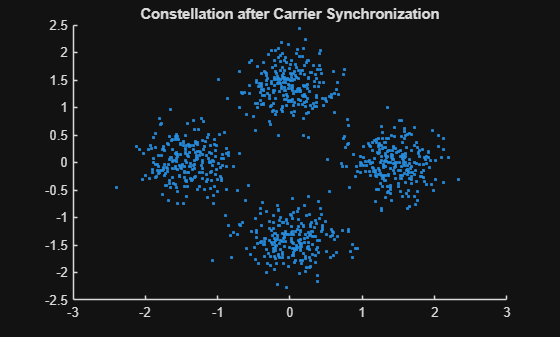


%% ----------------------------------
% 3. Carrier Synchronization (Phase Correction)
%% ----------------------------------
% Estimate phase (simple method)
phi_est = angle(mean(r.^4))/4;

% Correct phase
r_corrected = r .* exp(-1j*phi_est);

figure;
scatter(real(r_corrected), imag(r_corrected), '.');
title('Constellation after Carrier Synchronization');


%% ----------------------------------
% Detection
%% ----------------------------------
detected_b1 = real(r_corrected) > 0;
detected_b2 = imag(r_corrected) > 0;

BER = (sum(b1 ~= detected_b1) + sum(b2 ~= detected_b2)) / (2*N);
disp(['BER after synchronization: ', num2str(BER)]);

BER after synchronization: 0.2555


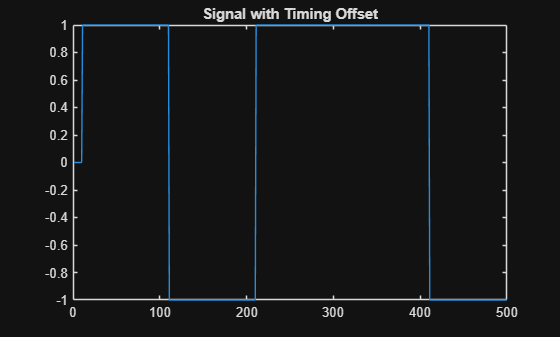


%% ----------------------------------
% 4. Clock Synchronization (Timing Offset)
%% ----------------------------------
% Introduce timing offset
offset = 10; % samples
signal = kron(real(s), ones(1,length(t)));

signal_offset = [zeros(1,offset), signal(1:end-offset)];

figure;
plot(signal_offset(1:500));
title('Signal with Timing Offset');

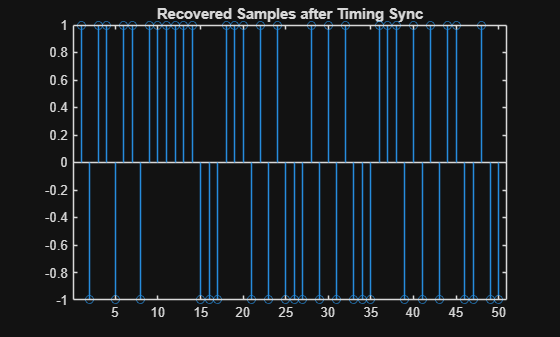


%% ----------------------------------
% Simple Timing Recovery (Peak Sampling)
%% ----------------------------------
samples = signal_offset(offset+length(t)/2:length(t):end);

figure;
stem(samples(1:50));
title('Recovered Samples after Timing Sync');

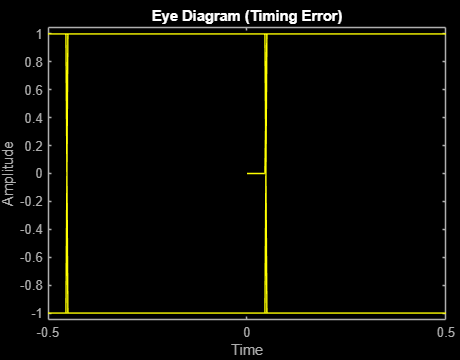


%% ----------------------------------
% 5. Eye Diagram
%% ----------------------------------
figure;
eyediagram(signal_offset, 2*length(t));
title('Eye Diagram (Timing Error)');